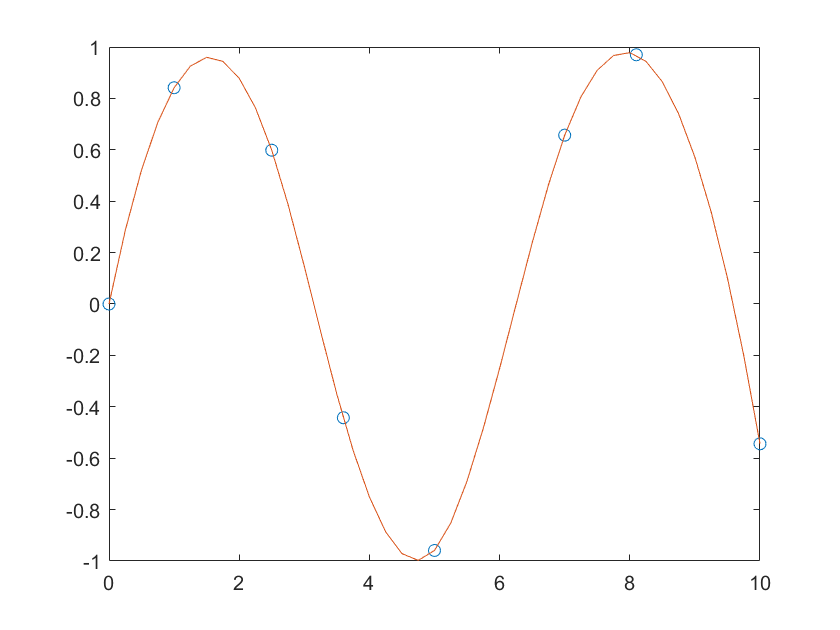

% splines 

% polinomic interpolation
x = [0 1 2.5 3.6 5 7 8.1 10];
y = sin(x);
xx = 0:.25:10;
yy = spline(x,y,xx);
plot(x,y,'o',xx,yy)


% extrapolation
t = 1900:10:1990;
p = [ 75.995  91.972  105.711  123.203  131.669 ...
     150.697 179.323  203.212  226.505  249.633 ];
% Extrapolate and predict the population in the year 2000 using a cubic spline.

spline(t,p,2000)

ans = 270.6060

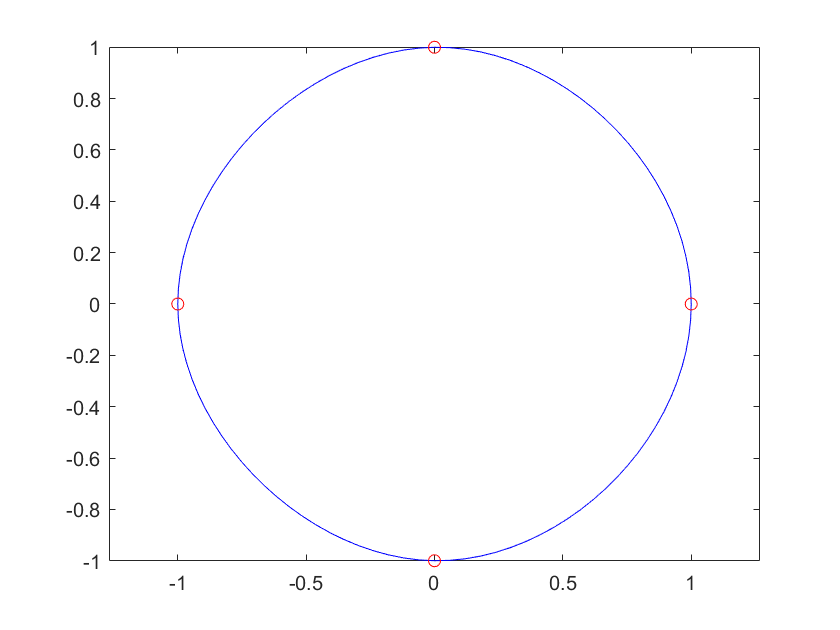


% angular data
x = pi*[0:.5:2]; 
y = [0  1  0 -1  0  1  0; 
     1  0  1  0 -1  0  1];
pp = spline(x,y);
yy = ppval(pp, linspace(0,2*pi,101));
plot(yy(1,:),yy(2,:),'-b',y(1,2:5),y(2,2:5),'or')
axis equal

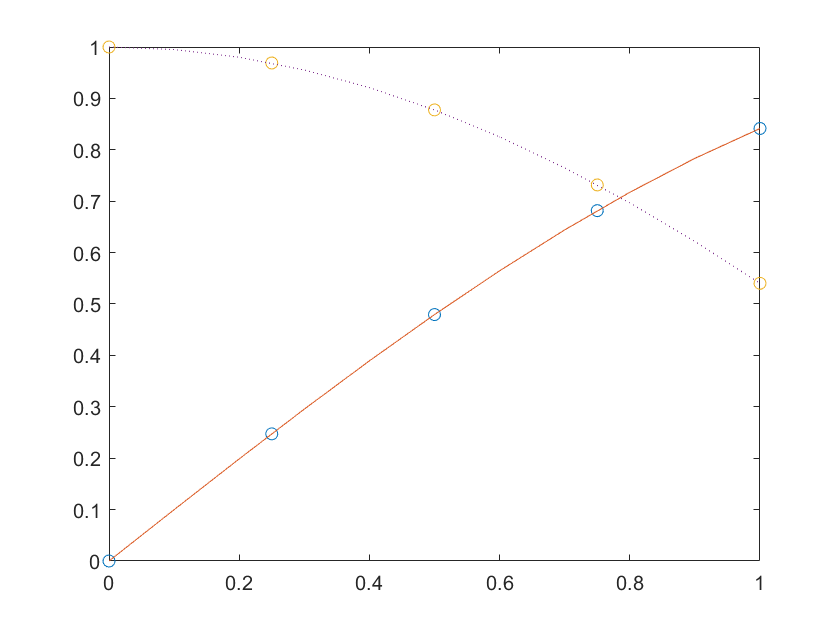


% trigonometric 
x = 0:.25:1;
Y = [sin(x); cos(x)];
xx = 0:.1:1;
YY = spline(x,Y,xx);
plot(x,Y(1,:),'o',xx,YY(1,:),'-')
hold on
plot(x,Y(2,:),'o',xx,YY(2,:),':')
hold off

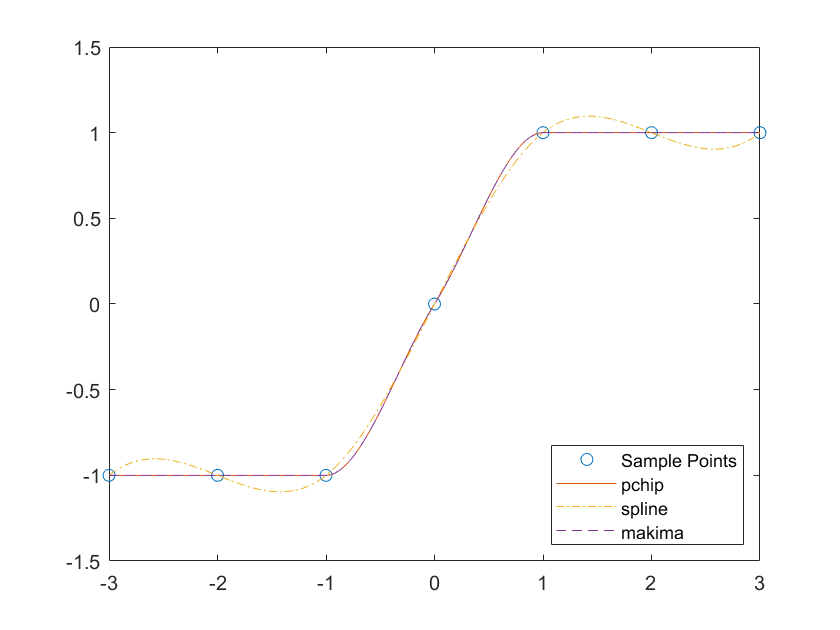


% pchip i nsk mes
x = -3:3; 
y = [-1 -1 -1 0 1 1 1]; 
xq1 = -3:.01:3;
p = pchip(x,y,xq1);
s = spline(x,y,xq1);
m = makima(x,y,xq1);
plot(x,y,'o',xq1,p,'-',xq1,s,'-.',xq1,m,'--')
legend('Sample Points','pchip','spline','makima','Location','SouthEast')

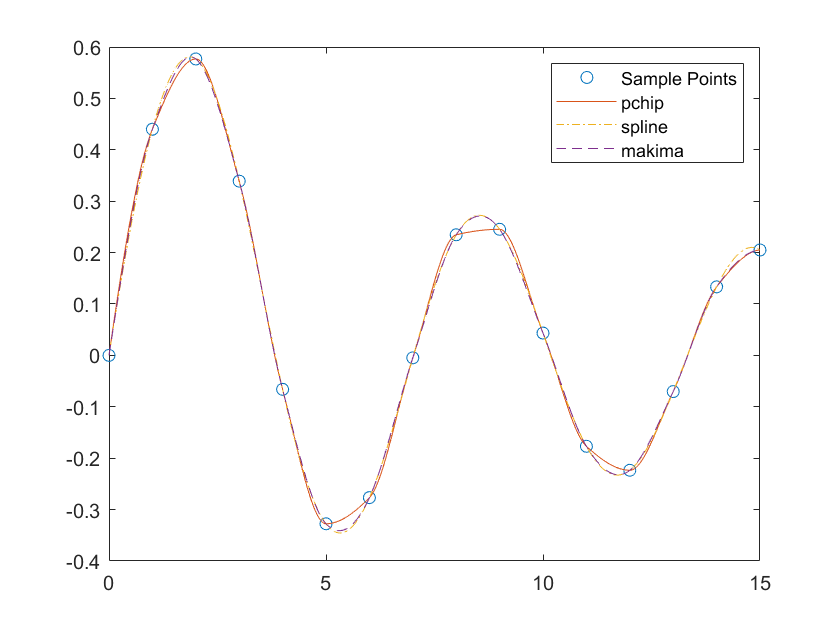


% bessel amb pchip i makima 
x = 0:15;
y = besselj(1,x);
xq2 = 0:0.01:15;
p = pchip(x,y,xq2);
s = spline(x,y,xq2);
m = makima(x,y,xq2);
plot(x,y,'o',xq2,p,'-',xq2,s,'-.',xq2,m,'--')
legend('Sample Points','pchip','spline','makima')